We can construct a Channel-Magnitude sequence with the following commands:

q1 = struct;
q1.channels = (1:6)';
q1.magnitudes = (10:10:60)';
q1.periods_us = 100; 

This sequence contains 6 pulses, on channels 1 through 6, with increasing magnitude. The default MATLAB display of a struct only shows the size of column vectors:

q1

q1 = struct with fields:
      channels: [6×1 double]
    magnitudes: [6×1 double]
    periods_us: 100

To display the sequence as text:

Disp_sequence(q1);

   channels magnitudes periods_us
          1         10        100
          2         20           
          3         30           
          4         40           
          5         50           
          6         60           


To plot the sequence:

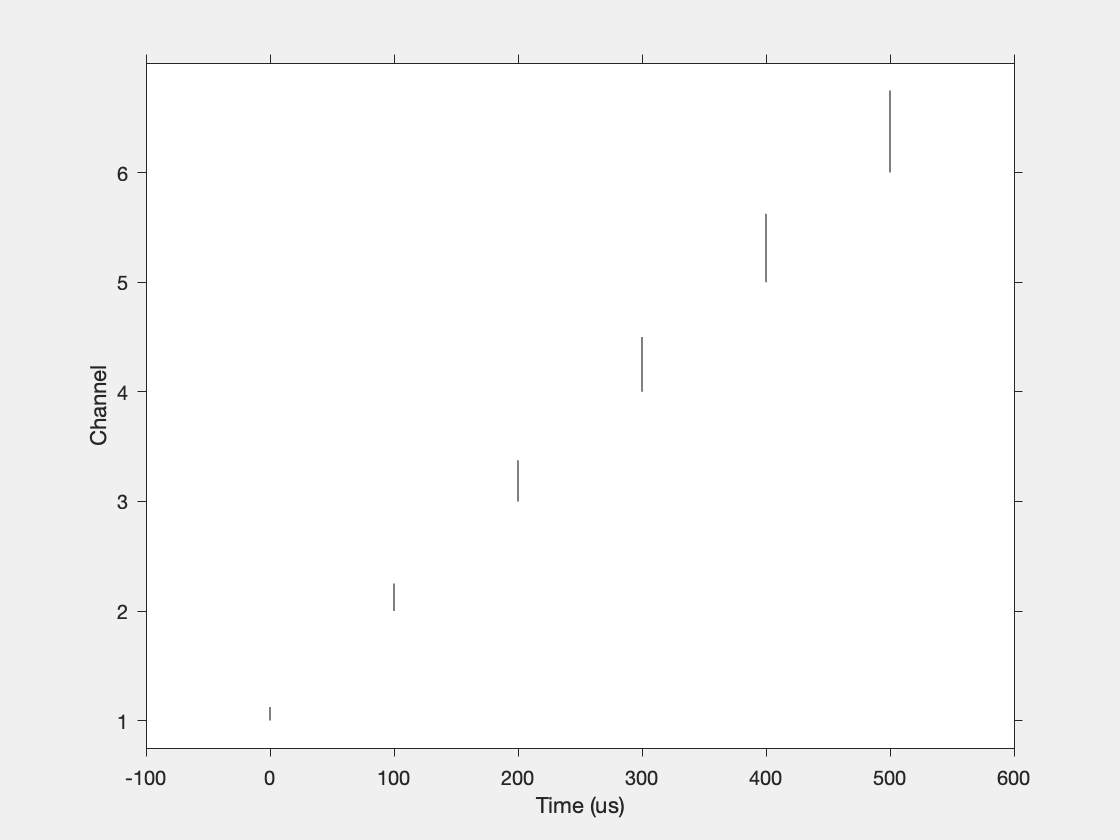

Plot_sequence(q1);

In the plot, each pulse is shown as a vertical line, with the base of the line aligned with the channel number. The height of the line is proportional to the magnitude of the pulse. The horizontal location of the line indicates the start time of the pulse. Channels are numbered from 1 (lowest frequency, most apical) to 6 (highest frequency, most basal). Note again that the Nucleus implant electrodes are numbered in the opposite direction.

To get the number of pulses in the sequence:

n = Get_num_pulses(q1)

n = 6

To get the duration of the sequence, and the start times of each pulse (in microseconds):

duration = Get_sequence_duration(q1)

duration = 600

times = Get_pulse_times(q1)

times =      0
   100
   200
   300
   400
   500


Note that the first pulse is defined to occur at time 0. For convenience, the sequence duration can be returned as a second output from `Get_pulse_times`, but note that there is no pulse at that time (see the plot of the sequence). The relationship between the periods and the times is:

all(diff([times; duration]) == q1.periods_us)

ans = logical
   1